# File Info

Andrew Brown 

10/18/20 GEEN 3853 

The purpose of this file is to analyze the class data from our coffee cup experiment. 

## Prepare workspace

clear all 
close all
clc

## LOAD DATA

%load as "table" for more versatility (readtable)

raw = readtable('CoffeeCupThresholdTimes.xlsx');

ds_full = raw;

%What is in this dataset? summary(ds), head(ds,3)
summary(ds_full)

Variables:

    Var1: 23×1 double

        Values:

            Min           1   
            Median       12   
            Max          23   

    Team_: 23×1 double

        Values:

            Min          1    
            Median       5    
            Max          8    

    Lid_NoLid: 23×1 cell array of character vectors

    Name: 23×1 cell array of character vectors

    UpperThresholdTime_s_: 23×1 double

        Values:

            Min       0.051354
            Median     0.64685
            Max        0.76626

    LowerThresholdTime_s_: 23×1 double

        Values:

            Min       0.061887
            Median     0.65808
            Max        0.78108

    TimeInIdealTempRange: 23×1 double

        Values:

            Min       0.0070602
            Median     0.010532
            Max        0.026736

    Time_min_: 23×1 double


## Simplify the dataset

ds = ds_full(:,8);
%head(ds, 1)

## Split into Lid and No Lid Arrays with only Times data

noLidData = table2array(ds(1:11,1));    % Stores the time in minutes the coffee stayed at the ideal temperature range with the lid off.
lidData = table2array(ds(12:22, 1));    % Stores the time in minutes the coffee stayed at the ideal temperature range with the lid on.
coffeeMugData = table2array(ds(23,1 )); % Stores the time in minutes the coffee stayed at the ideal temperature range in a coffee mug (only 1 peice of data).

## DESCRIPTIVE STATS - VISUAL

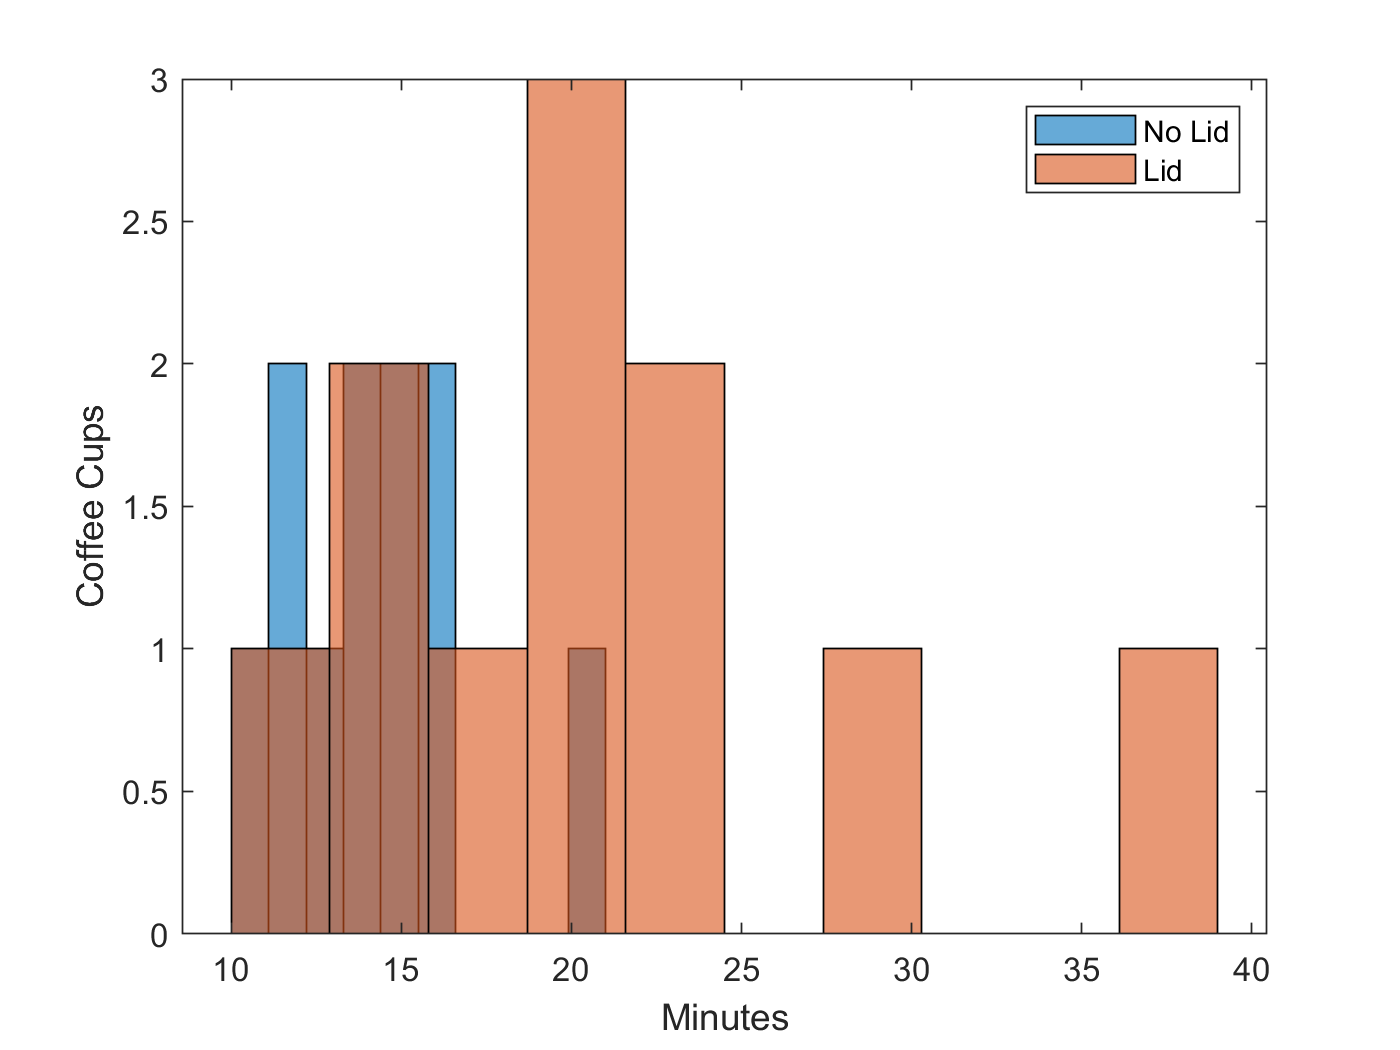

% %% Descriptive stats: Continuous
% Plot Coffee Data (Histogram)
figure
histogram(noLidData,10);
hold on
histogram(lidData,10);
xlabel('Minutes')
ylabel('Coffee Cups')
legend('No Lid', 'Lid')
hold off

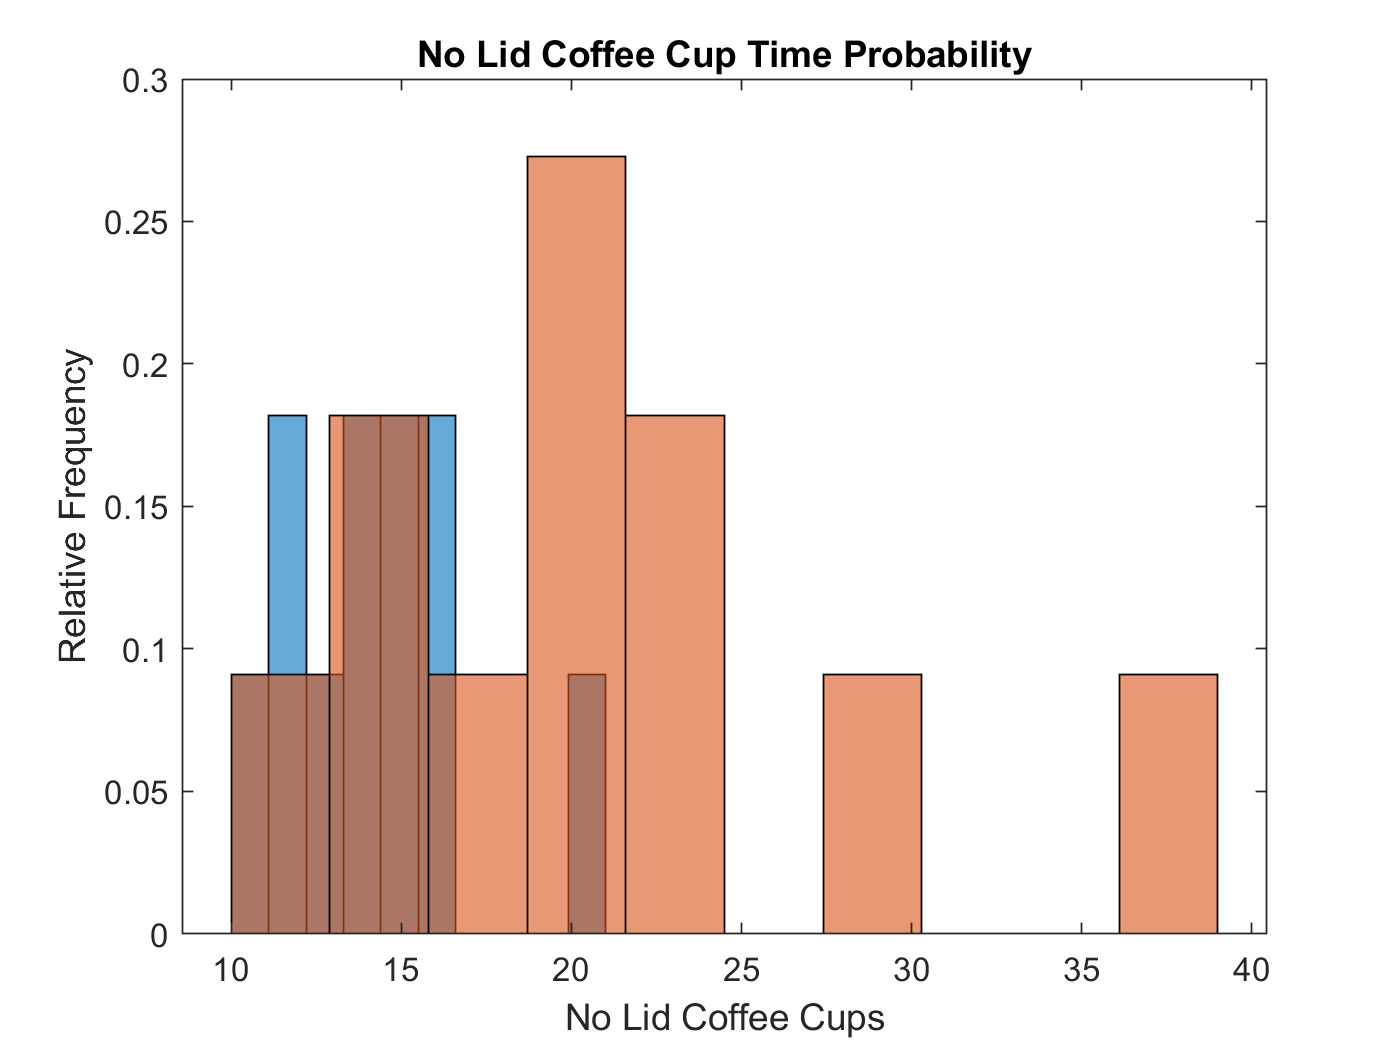

% Plot Coffee Cup Time Probabilities (Histogram)
figure
histogram(noLidData,10,'Normalization','probability');
hold on
h = histogram(lidData,10,'Normalization','probability');
xlabel('No Lid Coffee Cups')
ylabel('Relative Frequency')
title('No Lid Coffee Cup Time Probability')
hold off

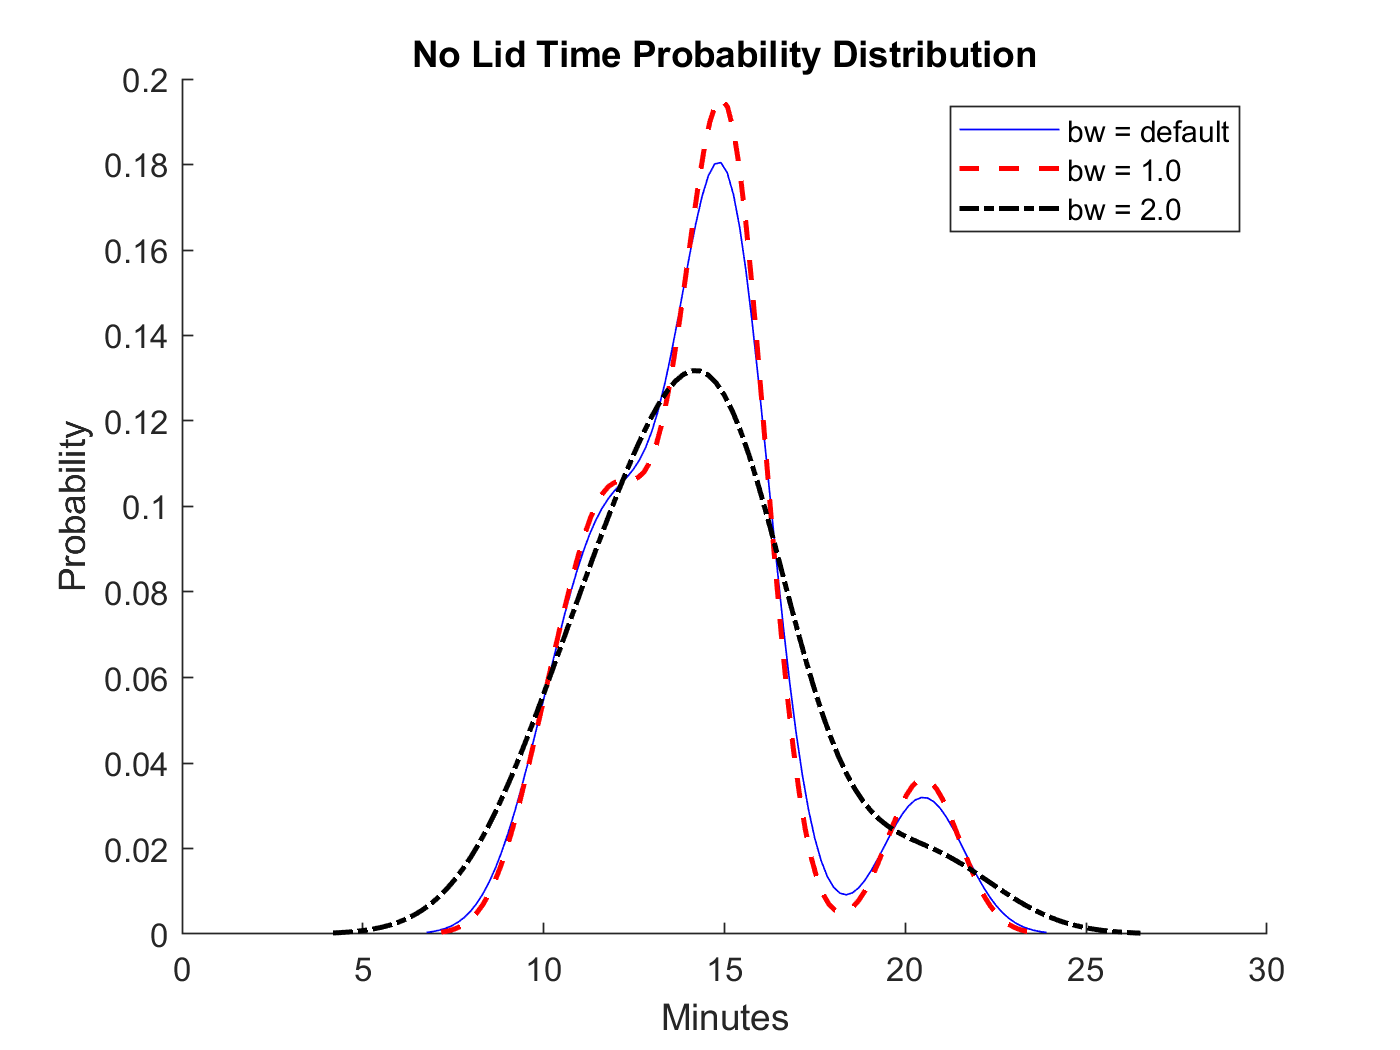

% Plot No Lid Probability Distribution Function based on this sample:
figure
hold on
[f,xi,bw] = ksdensity(noLidData); % Default bw is 1.1346
plot(xi,f,'blue')
[f,xi] = ksdensity(noLidData,'Bandwidth',1.0);
plot(xi,f,'--r','LineWidth',1.5)
[f,xi] = ksdensity(noLidData,'Bandwidth',2.0);
plot(xi,f,'-.k','LineWidth',1.5)
xlabel('Minutes')
ylabel('Probability')
legend('bw = default','bw = 1.0','bw = 2.0')
axis([0, 30, 0, 0.2]);
title("No Lid Time Probability Distribution")
hold off

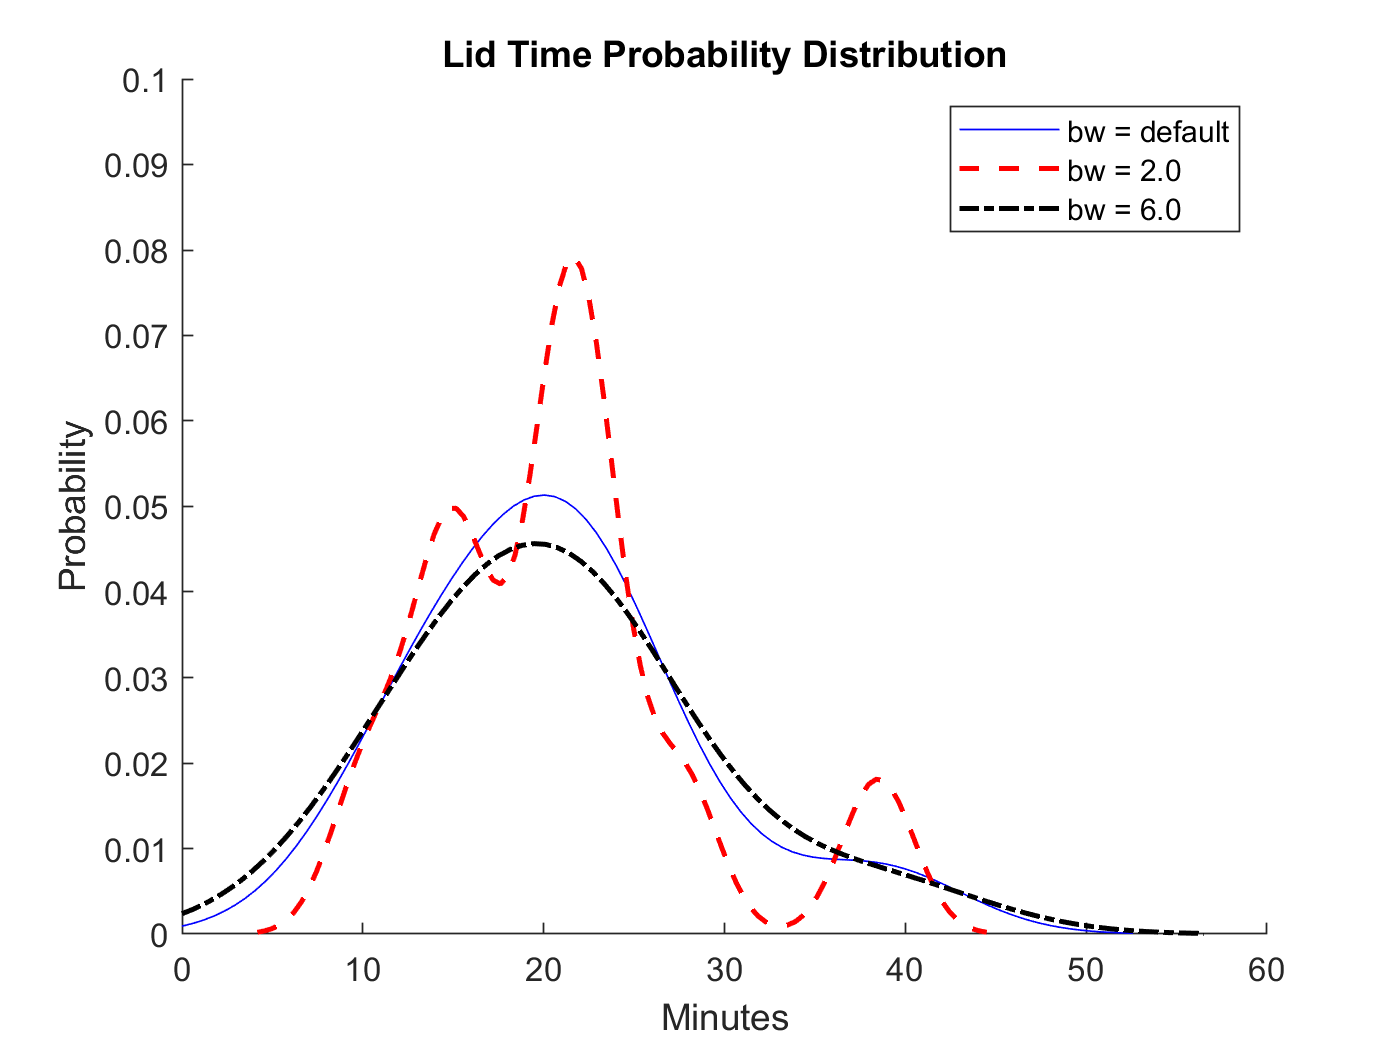

% Plot Lid Probability Distribution Function based on this sample:
figure
hold on
[f,xi,bw] = ksdensity(lidData); % Default bw is 4.6987
plot(xi,f,'blue')
[f,xi] = ksdensity(lidData,'Bandwidth',2.0);
plot(xi,f,'--r','LineWidth',1.5)
[f,xi] = ksdensity(lidData,'Bandwidth',6.0);
plot(xi,f,'-.k','LineWidth',1.5)
xlabel('Minutes')
ylabel('Probability')
legend('bw = default','bw = 2.0','bw = 6.0')
axis([0, 60, 0, 0.1]);
title("Lid Time Probability Distribution")
hold off

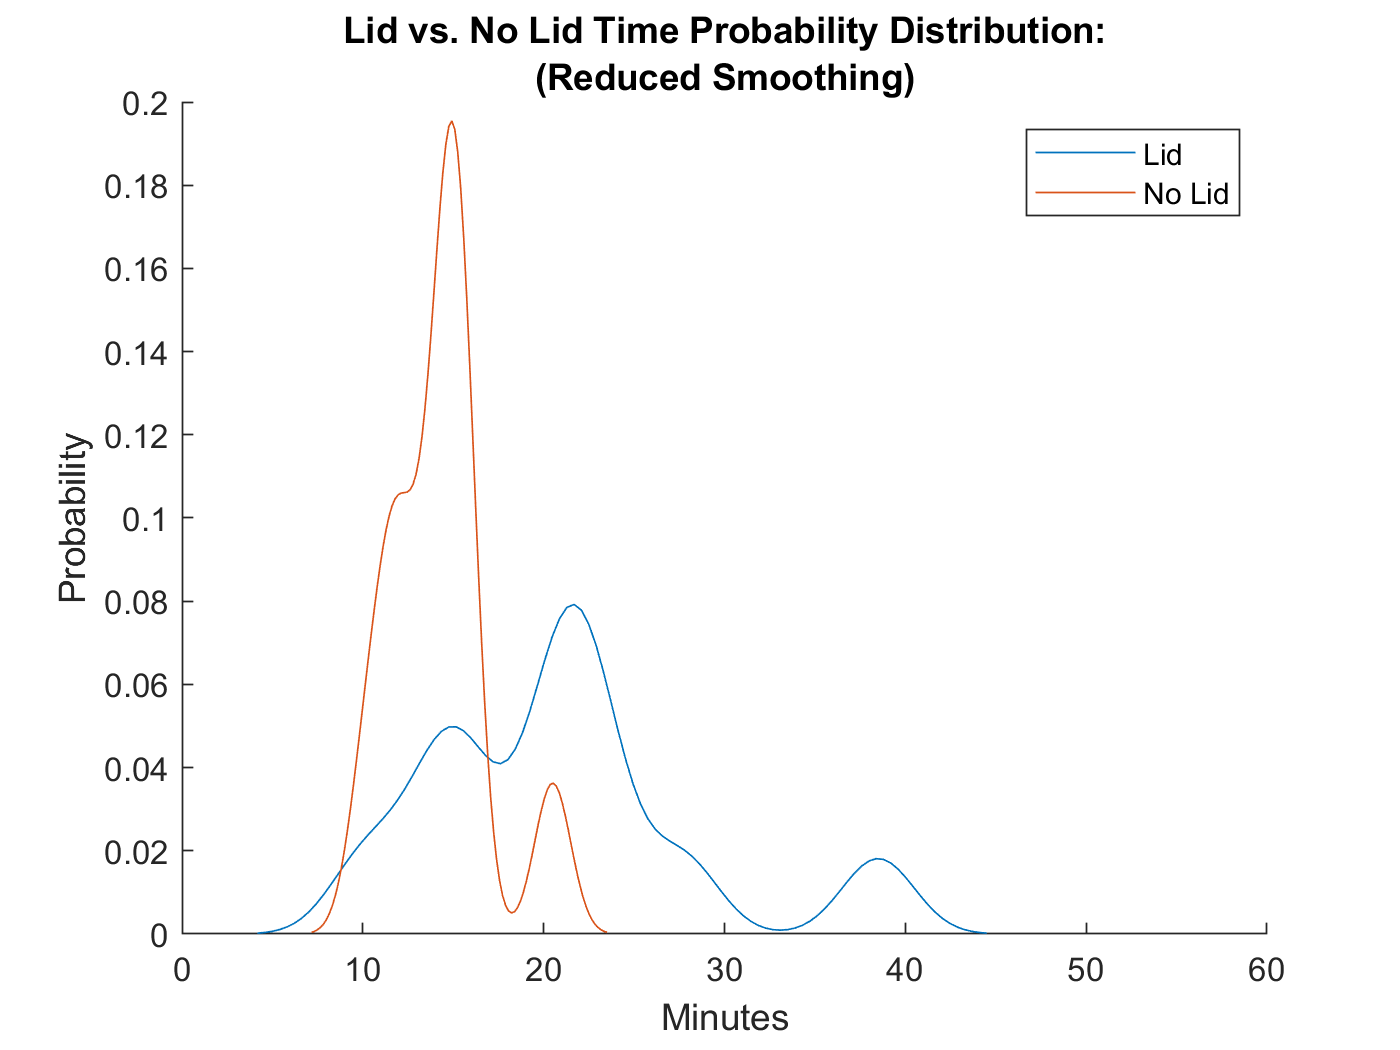

% Low Bandwidth Combination Probability Distributions
figure
hold on
[f,xi] = ksdensity(lidData,'Bandwidth',2.0);
plot(xi,f)
[f,xi] = ksdensity(noLidData,'Bandwidth',1.0);
plot(xi,f)
xlabel('Minutes')
ylabel('Probability')
legend('Lid','No Lid')
axis([0, 60, 0, 0.2]);
title("Lid vs. No Lid Time Probability Distribution:"+newline+"(Reduced Smoothing)")
hold off

**Takeaways: **From the historgrams and the probability distributions, it is clear that both the Mean and Standard Deviation for the lids is higher than thoss of the no lid samples.

## DESCRIPTIVE STATS - NUMERIC

Mean (mean)

% Mean (mean)
mnD = nanmean(noLidData)

mnD = 14.2319

% Median (median)
medD = nanmedian(noLidData)

medD = 14.3333

% Mode (mode)
modD = mode(noLidData)

modD = 10.1667

%When multiple values occur equally frequently, mode returns the smallest #

% Standard Deviation (std)
sdD = nanstd(noLidData)

sdD = 2.7486

% Variance (var)
varD = nanvar(noLidData)

varD = 7.5546

% Range (max() - min() or range)
rgD = range(noLidData)

rgD = 10.3333

% Mean (mean)
mnR = nanmean(lidData)

mnR = 20.8636

% Median (median)
medR = nanmedian(lidData)

medR = 21.0000

% Mode (mode)
modR = mode(lidData)

modR = 10.1667

%When multiple values occur equally frequently, mode returns the smallest #

% Standard Deviation (std)
sdR = nanstd(lidData)

sdR = 7.6757

% Variance (var)
varR = nanvar(lidData)

varR = 58.9156

% Range (max() - min() or range)
rgR = range(lidData)

rgR = 28.3333

## INFERRENTIAL STATISTICS

In order to use some of the most common inferrential parrametric tests, we first need to know if the data in each of our samples is normally distributed. To find this out, we will conduct a test of normality. If it is, an FTest will then be run to find out if the variances have a statistically significant difference. Then, a TTest will be run to find if means have a statistically significant difference using the results of the FTest.

### NORMALITY PLOTS

The normplots seen below indicate normality if the individual data points generally fall on the linear regression line

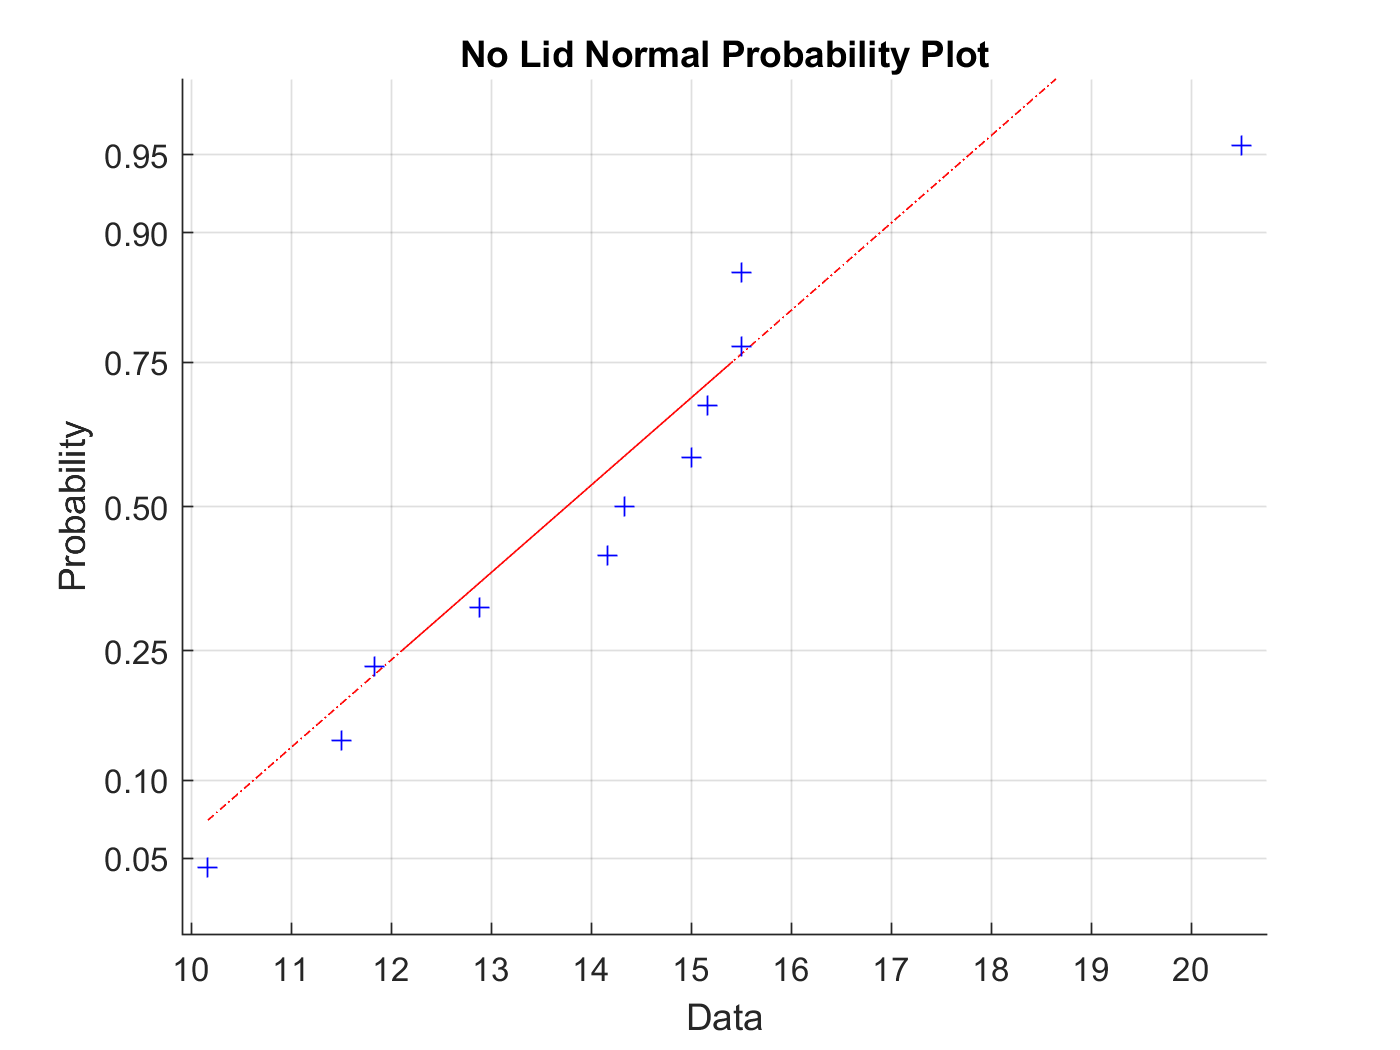

%Plot the data. The "normplot" function makes a normal probabiltiy plot of
%the data.
figure
normplot (noLidData)
title('No Lid Normal Probability Plot');

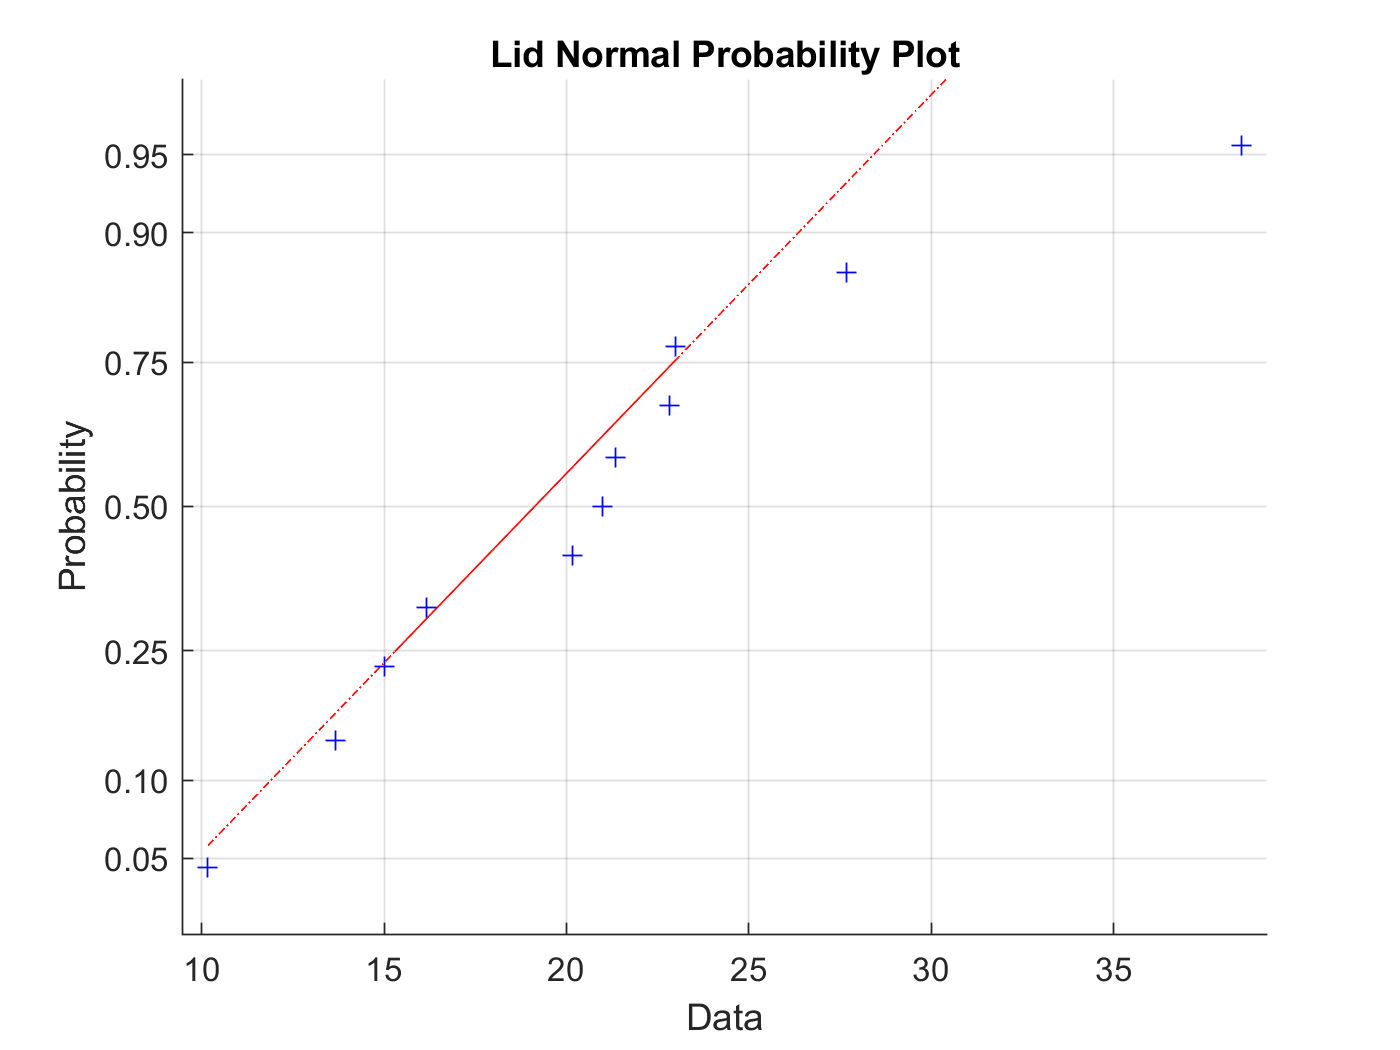

figure
normplot (lidData)
title('Lid Normal Probability Plot');

**Takeaways: **From the nomal probability plots, we can see that the data points seem to follow the lines of regression, indicating normality. Further use of the ADTest is necessary, though to confirm this hypothesis.

## TEST OF NORMALITY

For a two sample, independent test, we need to test the normality of each group using the Anderson-Darling Test.

Underlying Assumptions of the Anderson-Darling Test:

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

Step 1: (Note that a non-directional test is assumed.)

    H0: y_3 & y_4 are equal to zero.

    H1: y_3 & y_4 are not equal to zero.

Step 2: An Alpha Level of 0.05 will be used.

Step 3: The Anderson-Darling Test Statistic (ADTest) will be used.

Step 4: An Anderson-Darling Random Sample Distribution (RSD) will be used, and it is an exact test.

Step 5: The Critical Value (CV) for rejecting our null hypothesis (H0)  will be quantitative:

    *Reject H0 if any p-value < alpha.*

Step 6: Calculations

#### ADTest for Normality

%Next we want to use the "adtest" function to run the Anderson-Darling 
%goodness-of-fit test. Often we reject the null hypothesis (that data is 
%normally distributed) with significance level of 0.05.
%The Null hypothesis can be rejected if 
%ADTEST > Critical Value (CV). For more information, remember that you can
%always use the "help" function in Matlab.

[H,P,ADSTAT,CV]=adtest(noLidData, 'Alpha', 0.05)

H = logical
   0


P = 0.2765

ADSTAT = 0.4208

CV = 0.6924

[H,P,ADSTAT,CV]=adtest(lidData, 'Alpha', 0.05)

H = logical
   0


P = 0.3661

ADSTAT = 0.3736

CV = 0.6924

Step 7: 

a) Decison: Fail to reject H0

b) No Lid: p = 0.2765     Lid: p = 0.3661 

c) We have sufficient statistical evidence to infer that the population from which these data were randomly sampled is symmetrical and mesokurtic, and, therefore, may be approximated by the Normal distribution based on n = 11, the AD test is appropriate for this analysis.

## TEST OF VARIANCE

In order to know whether our Ttest assumes equal or unequal variances, we will use an F test to determine if thee variances are equal or unequal.

Underlying Assumptions of the Test:

- The data are continuous.

- The data are from a sample that was randomly  drawn from a process/population.

- The data are normally distributed (all groups).

Method: For a two-sample, independent test: F test.

Step 1: (Note that a non-directional test is assumed)

    H0: The variances of the No Lid sample and the Lid sample are equal.

    H1: The variances of the No Lid sample and the Lid sample are not equal.

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make will be the same as that for the normality test: 0.05.

Step 3: The F statistic will be used.

Step 4: We will use the RSD for F with (n1-1,n2-1) degrees of freedom and it is an exact test.

Step 5: The Critical Value (CV) for rejecting our null hypothesis (H0)  will be quantitative:

    *Reject H0 if any p-value < alpha OR F_stat < F_crit.*

Step 6: Calculations

#### FTest for Variance

% Calculate the variances directly.
noLidVariance = (std(noLidData))^2

noLidVariance = 7.5546

lidVariance = (std(lidData))^2

lidVariance = 58.9156

% Calculate a 2 sample ftest to see if the samples has statistically
% significant variances.
[H,P,CI,STATS] = vartest2(noLidData,lidData,'alpha',0.05,'tail','both')

H = 1

P = 0.0032

CI =     0.0345
    0.4766


STATS = struct with fields:
    fstat: 0.1282
      df1: 10
      df2: 10


Step 7: 

a) Decison: Reject H0

b) p = 0.0032 (Less than alpha)

c) We have sufficient statistical evidence to infer that the variances of the populations from which these data were randomly sampled are different.

## TEST OF LOCATION

Using the resuslts of the previous two inferrential tests, we will use a test of location to find of the means are statistically different from each other.

Underlying Assumptions of the Test:

- The data are continuous.

- The data are from a randomly-drawn sample from a process/population (independent specimens).

- 2-group, Independent, Unequal Variences may be known or assumed.

Method: Two-sample, independent T-Test.

Step 1: (Noe that a non-directional test is assumed.)

    H0: Means of No Lid data and Lid data are equal.

    H1: Means of No Lid data and Lid data are unequal.

Step 2: An Alpha Level of 0.05 will be used.

Step 3: The t-statistic for a 2-sample, independent test of means and pooled variances will be used.

Step 4: We will use the RSD for t with (n1+n2-2) degrees of freedom and it is an exact test.

Step 5: The Critical Value (CV) for rejecting our null hypothesis (H0)  will be quantitative:

    *Reject H0 if any p-value < alpha OR T_stat < F_crit.*

*Step 6: Calculations*

####  TTest for Means

% We will do a 2 sample ttest to test the two samples means. They will be
% two tailed and, as indicated from the above variences, have assumed
% unequal variences.

alpha1 = 0.05;

[H,P,CI,STATS] = ttest2(noLidData,lidData,'alpha',alpha1,'tail','both','Vartype','unequal')

H = 1

P = 0.0188

CI =   -11.9630
   -1.3005


STATS = struct with fields:
    tstat: -2.6978
       df: 12.5231
       sd: [2×1 double]


Step 7: 

a) Decison: Reject H0

b) p = 0.0188 (Less than alpha)

c) We have sufficient statistical evidence to infer that themeans of the populations from which these data were randomly sampled are different.

## Conclusion

The Anderson-Darling tests on both sets of data failed to reject the null hypothesis that the data is normally distributed. Using that result, we can assume normality, and use the ftest and ttest. The ttest using a 95% confidence interval resulted in the rejection of the null hypothesis that the means are statistically the same, allowing us to conlude that because the lid data has a statistically significant higher average value of about 21 minutes as compared to the no lid data's average of 14 minutes, a lid on a coffee cup will reliably keep coffee at its ideal drinking temperature for longer. However, from the adtest, we can also conclude the that increase in variability due to the lid makes the exact increase in time in the ideal drinking temperature range unpredictable. 